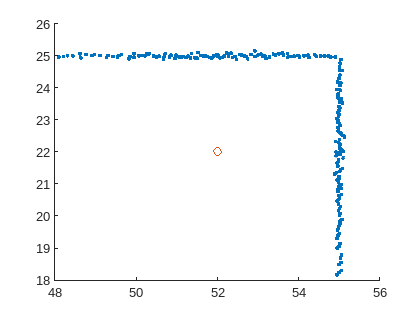

id = 1;
pos = [52;22];
rad = 5;
[b,a]=lidar_sim(obstacles,pos,rad,360);
a(1,:) = a(1,:) + 0.05*randn(1,length(a));
a(2,:) = a(2,:);
a(2,:) =adjust_angle(a(2,:));

figure
hold on 
plot(pos(1)+a(1,:).*cos(a(2,:)),pos(2)+a(1,:).*sin(a(2,:)),'.')
plot(pos(1),pos(2),'o')

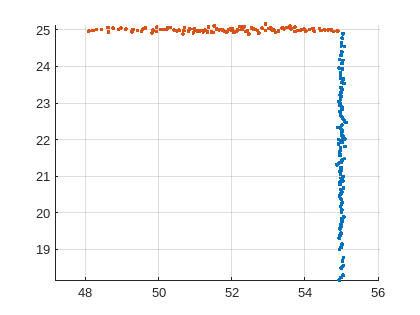


K=regr_scan(a,pos,0.25);
figure
hold on 
grid on
axis equal
for i=1:length(K)
plot(K{i}(1,:),K{i}(2,:),'.')
end

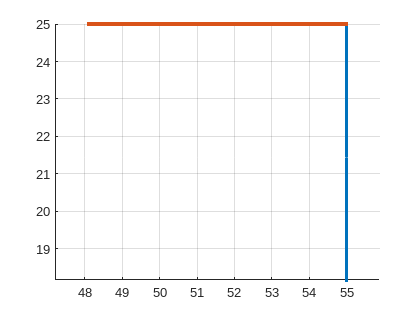


KK = inflate(K,0,pos);
KR = inflate(K,0.5,pos);
k_int=horzcat(KR{:});
k_int = interp1(k_int(2,:),k_int(1,:));
% figure
% hold on 
% grid on
% axis equal
%plot(pos(1)+a(1,:).*cos(a(2,:)),pos(2)+a(1,:).*sin(a(2,:)),'.')
figure
hold on 
grid on
axis equal
for i=1:length(KK)
plot(KK{i}(1,:),KK{i}(2,:),'.')
end

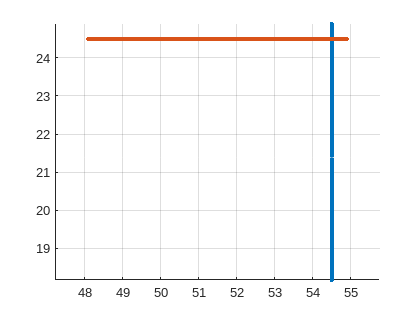

figure
hold on 
grid on
axis equal
for i=1:length(KR)
plot(KR{i}(1,:),KR{i}(2,:),'.')
end

% plot(K{1}(1,:),K{1}(2,:),'.')
% plot(K{2}(1,:),K{2}(2,:),'.')
% 
% figure
% plot(k_int(1,:),k_int(2,:),'.')
bots(id).pos=[52;22;0];
bots(id).pos_est=[52;22;0]

bots =   1×7 DiffBot array with properties:

    x
    y
    pos
    neighbours
    neighbours_unc
    obst
    obsts_lidar
    sizes
    grid_size
    dt
    rs
    Rs
    rs_min
    verts
    verts_unc
    verts_qt
    verts_qtnosi
    verts_zi
    verts_meas
    id
    cell_mass
    prev_cell_center
    cell_center
    steps_vert
    noise_model_std
    gps_noise_std
    mag_noise_std
    P
    pos_est
    mesh_map
    mesh_map_meas
    firstupdate_qt
    bot_dim
    phi__
    kd
    ku
    Ppred
    kg
    kl
    rendezvous_yes
    discover_target
    rendezvous_pt
    target_pt
    set_pt
    rend_id
    rho_d_th
    zeroer
    target_pos
    ki
    rho_i
    rho_i_D
    u_clip
    w_clip


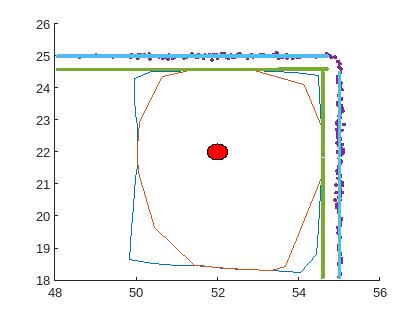

bots=update_obstacles(obstacles,bots,n_lidar);
[c,b]=bots(id).vertex_unc2;
figure
hold on
bots(id).plot_bot
plot(bots(id).pos_est(1)+bots(id).obsts_lidar(1,:).*cos(bots(id).obsts_lidar(2,:)),bots(id).pos_est(2)+ bots(id).obsts_lidar(1,:).*sin(bots(id).obsts_lidar(2,:)),'.')
plot(bots(id).pos_est(1)+c(1,:).*cos(c(2,:)),bots(id).pos_est(2)+ c(1,:).*sin(c(2,:)),'.')
plot(bots(id).pos_est(1)+b(1,:).*cos(b(2,:)),bots(id).pos_est(2)+ b(1,:).*sin(b(2,:)),'.')

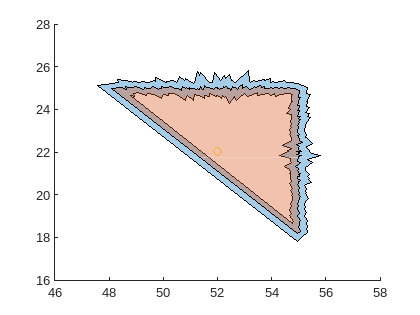

b=polar2cartesian(a,pos);
c=polyshape(b');
poly = polybuffer(b','lines',0.25,'JointType','miter');
figure
hold on
plot(poly)
plot(c)
plot(pos(1),pos(2),'o')

id =7;
xc=bots(id).pos_est(1,1)-0.5;
yc=bots(id).pos_est(2,1);


% 
% figure 
% hold on
% bots(id).plot_bot

%bots(2).steps_vert = 101;

rad = 4

rad = 4

%%bots(2).rs=30/2.2;
%update_obstacles(obstacles,bots,n_lidar);
%pp=bots(2).vertex_unc2
[b,a]=lidar_sim(obstacles,[xc;yc],rad,360);

a(1,:)=a(1,:)+1*0.05*randn(1,size(a,2));

Index in position 1 exceeds array bounds.

a(2,:)=a(2,:)+0*bots(id).pos(3);
a(2,:) = adjust_angle(a(2,:));

figure 
hold on
bots(id).plot_bot
plot(bots(id).verts_zi(1,:),bots(id).verts_zi(2,:),'.')
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')
update_obstacles(obstacles,bots,n_lidar);

bots(id).vertex_unc2
figure 
axis equal
hold on
plot(xc,yc,'o',MarkerSize=10)
%plot(a(1,:).*cos(a(2,:)),a(1,:).*sin(a(2,:)),'.')

obst = regr_scan(a,[xc;yc],0.2);
obst = inflate(obst,bots(id).uncertainty+bots(id).bot_dim+3.*0.02,bots(id).pos);
bots(id).plot_bot

for i=1:length(obst)
plot(obst{i}(1,:),obst{i}(2,:),'.')
end
